# Marginal cost data regression using CVX

## Load cleaned marginal cost data

load("cleanedQMCTables.mat");
plot_data = cell(8,2);
parameter = [];

cleanedTable = selCleanedPartQMCTables{1}

cleanedTable = 2022×6 table
    Awarded    median_MCMarket    cleanedMedian_MCMarket    MCMarket       Date       Hour
    _______    _______________    ______________________    ________    __________    ____

     143.7         24.798                 24.798             24.798     06/29/2019     21 
       194         16.995                 16.995             16.995     09/20/2019      0 
       195         16.852                 16.852             16.862     09/20/2019      1 
       195         16.852                 16.852             16.852     09/20/2019      2 
       195         16.852                 16.852             17.917     09/20/2019      5 
       261          15.98                  15.98             16.032     05/24/2019      4 
       261          15.98              

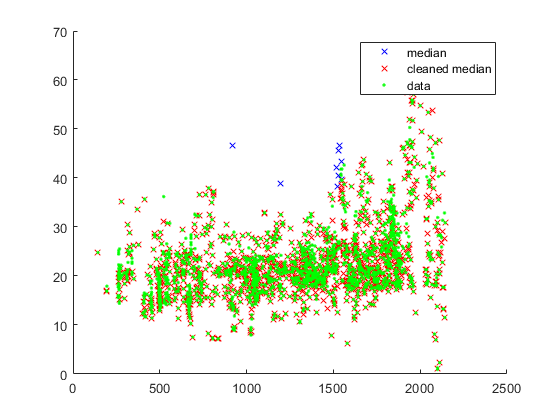

figure;
scatter(cleanedTable.Awarded, cleanedTable.median_MCMarket, 'bx');
hold on;
scatter(cleanedTable.Awarded, cleanedTable.cleanedMedian_MCMarket, 'rx');
scatter(cleanedTable.Awarded, cleanedTable.MCMarket, 'g.');
hold off;
legend("median", "cleaned median", "data");

## Fit linear relation using CVX

for i = 1:8
    cleanedPrice = selCleanedPartQMCTables{i}.cleanedMedian_MCMarket;
    cleanedQuantity = selCleanedPartQMCTables{i}.Awarded;
    plot_data{i,1} = cleanedQuantity;
    plot_data{i,2} = cleanedPrice;
    cvx_begin quiet
        variable A
        variable b
        minimize( norm( cleanedPrice-(A*cleanedQuantity+b)) );
        cvx_end
    parameter = [parameter;[A b]];
end

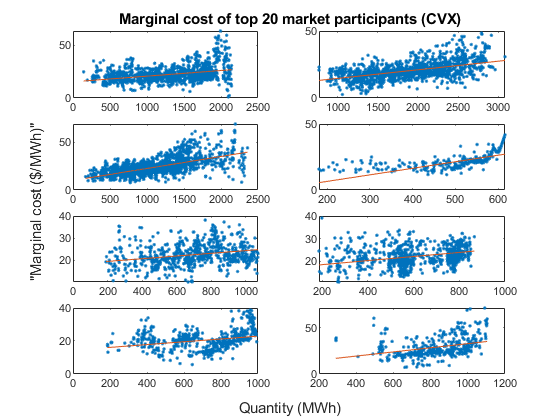

cvx_y = 8×1 cell array
    {2022×1 double}
    {2004×1 double}
    {2119×1 double}
    {1630×1 double}
    {1490×1 double}
    {1378×1 double}
    {1194×1 double}
    { 778×1 double}


cvx_y = multiplot(plot_data, parameter,8, 1)

y_pred_linear = cvx_y;

## RMSE

corrQuad = zeros(8, 1);
RMSEQuad = zeros(8, 1);
for n=1:8
    partCleanedQMCTable = selCleanedPartQMCTables{n};
    cvx_pre = cvx_y{n};
    % Calculate correlation coefficient
    quadR= corrcoef(partCleanedQMCTable.MCMarket, cvx_pre);
    corrQuad(n)= quadR(1, 2);
    % Calculate RMSE
    RMSEQuad(n) = sqrt(mean((partCleanedQMCTable.MCMarket-cvx_pre).^2));
end
selPartCorrTable_linear = table(corrQuad, RMSEQuad)

selPartCorrTable_linear = 8×2 table
    corrQuad    RMSEQuad
    ________    ________

    0.39494      6.5909 
    0.52041      5.2342 
     0.6281      6.3347 
    0.54045      5.6848 
    0.28932      4.7301 
    0.40395      5.0828 
    0.32981      4.9922 
     0.3353      10.513 


## Fit quadratic relation using CVX

plot_data = cell(8,2);
parameter = [];
for i = 1:8
    cleanedPrice = selCleanedPartQMCTables{i}.cleanedMedian_MCMarket;
    cleanedQuantity = selCleanedPartQMCTables{i}.Awarded;
    plot_data{i,1} = cleanedQuantity;
    plot_data{i,2} = cleanedPrice;
    cvx_begin quiet
        variable A
        variable B
        variable C
        minimize( norm( cleanedPrice-(A*cleanedQuantity.^2+B*cleanedQuantity+C)) );
        cvx_end
        parameter = [parameter;[A B C]];
end

 
Calling Gurobi 9.00: 1506 variables, 1502 equality constraints
------------------------------------------------------------
Gurobi Optimizer, licensed to CVX for CVX
Academic license - for non-commercial use only
Gurobi Optimizer version 9.0.0 build v9.0.0rc2 (win64)
Optimize a model with 1502 rows, 1506 columns and 6008 nonzeros
Model fingerprint: 0x78c3a94d
Model has 1 quadratic constraint
Coefficient statistics:
  Matrix range     [1e+00, 8e+06]
  QMatrix range    [1e+00, 1e+00]
  Objective range  [1e+00, 1e+00]
  Bounds range     [0e+00, 0e+00]
  RHS range        [2e+00, 1e+02]
Presolve time: 0.01s
Presolved: 1502 rows, 1506 columns, 6008 nonzeros
Presolved model has 1 second-order cone constraint
Ordering time: 0.00s

Barrier statistics:
 Dense cols : 4
 Free vars  : 3
 AA' NZ     : 6.008e+03
 Factor NZ  : 7.520e+03 (roughly 1 MByte of memory)
 Factor Ops : 3.758e+04 (less than 1 second per iteration)
 Threads    : 1

                  Objective                Residual
Iter     

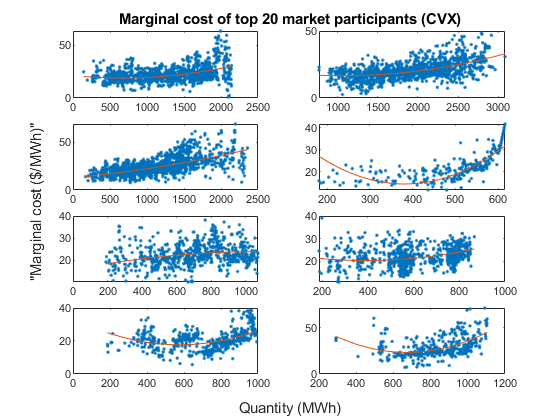

% PLOT
cvx_y = multiplot(plot_data, parameter, 8, 2);

for i=1:8
    selCleanedPartQMCTables{i}.MCQuadFit = cvx_y{i};
end

## RMSE

corrQuad = zeros(8, 1);
RMSEQuad = zeros(8, 1);
for n=1:8
    partCleanedQMCTable = selCleanedPartQMCTables{n};
    cvx_pre = cvx_y{n};
    % Calculate correlation coefficient
    quadR= corrcoef(partCleanedQMCTable.MCMarket, cvx_pre);
    corrQuad(n)= quadR(1, 2);
    % Calculate RMSE
    RMSEQuad(n) = sqrt(mean((partCleanedQMCTable.MCMarket-cvx_pre).^2));
end
selPartCorrTable_quad = table(corrQuad, RMSEQuad)

selPartCorrTable_quad = 8×2 table
    corrQuad    RMSEQuad
    ________    ________

    0.44037      6.4423 
    0.54313      5.1474 
    0.63138      6.3131 
    0.69213      5.0065 
    0.29733      4.7179 
    0.45922      4.9704 
    0.46189      4.6926 
    0.48616      9.7631 


## Cubic CVX

plot_data = cell(8,2);
parameter = [];
for i = 1:8
    cleanedPrice = selCleanedPartQMCTables{i}.cleanedMedian_MCMarket;
    cleanedQuantity = selCleanedPartQMCTables{i}.Awarded;
    plot_data{i,1} = cleanedQuantity;
    plot_data{i,2} = cleanedPrice;
    cvx_begin quiet
        variable A
        variable B
        variable C
        variable D
        minimize( norm( cleanedPrice-(A*cleanedQuantity.^3+B*cleanedQuantity.^2+C*cleanedQuantity + D)) );
    cvx_end
    parameter = [parameter;[A B C D]];
end

 
Calling Gurobi 9.00: 1507 variables, 1502 equality constraints
------------------------------------------------------------
Gurobi Optimizer, licensed to CVX for CVX
Academic license - for non-commercial use only
Gurobi Optimizer version 9.0.0 build v9.0.0rc2 (win64)
Optimize a model with 1502 rows, 1507 columns and 7510 nonzeros
Model fingerprint: 0x38570770
Model has 1 quadratic constraint
Coefficient statistics:
  Matrix range     [1e+00, 2e+10]
  QMatrix range    [1e+00, 1e+00]
  Objective range  [1e+00, 1e+00]
  Bounds range     [0e+00, 0e+00]
  RHS range        [2e+00, 1e+02]
         Consider reformulating model or setting NumericFocus parameter
         to avoid numerical issues.
Presolve time: 0.01s
Presolved: 1502 rows, 1507 columns, 7510 nonzeros
Presolved model has 1 second-order cone constraint
Ordering time: 0.00s

Barrier statistics:
 Dense cols : 5
 Free vars  : 4
 AA' NZ     : 7.510e+03
 Factor NZ  : 9.027e+03 (roughl

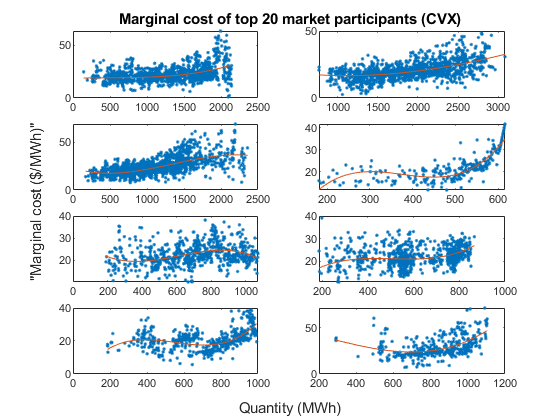

% PLOT
cvx_y = multiplot(plot_data, parameter, 8, 3);

for i=1:8
    selCleanedPartQMCTables{i}.MCCubicFit = cvx_y{i};
end

## RMSE

corrQuad = zeros(8, 1);
RMSEQuad = zeros(8, 1);
for n=1:8
    partCleanedQMCTable = selCleanedPartQMCTables{n};
    cvx_pre = cvx_y{n};
    % Calculate correlation coefficient
    quadR= corrcoef(partCleanedQMCTable.MCMarket, cvx_pre);
    corrQuad(n)= quadR(1, 2);
    % Calculate RMSE
    RMSEQuad(n) = sqrt(mean((partCleanedQMCTable.MCMarket-cvx_pre).^2));
end
selPartCorrTable_cubic = table(corrQuad, RMSEQuad)

selPartCorrTable_cubic = 8×2 table
    corrQuad    RMSEQuad
    ________    ________

    0.44169      6.4376 
     0.5433      5.1469 
      0.643      6.2349 
    0.73512      4.7607 
    0.35285      4.6243 
    0.52467      4.8232 
    0.55006       4.422 
    0.48801      9.7515 
